# ECE 101 - Polynomials and Numerical Analysis

Michael Dekoski

5-5-23

clc
clear

## Polynomials as Vectors

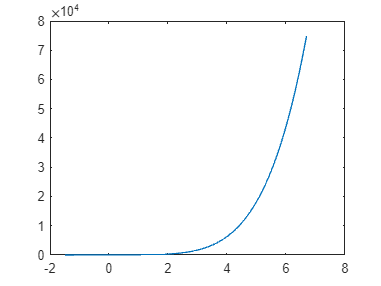

firstOrderVal = polyval([8 5], 9);

secOrderPoly = [2 4 10];
secondOrderVal = polyval(secOrderPoly, 3);

fifthOrderPoly = [5 3 4 6 7 0];
fifthOrderX = [-1.5:0.1:6.7];
fifthOrderY = polyval(fifthOrderPoly, fifthOrderX);

plot(fifthOrderX, fifthOrderY)

## Finding Roots of Polynomial

secOrderRoots = roots(secOrderPoly);

complexRoot1 = complex(-1,2);
complexRoot2 = complex(-1,-2);
secOrderRootsHand = [complexRoot1; complexRoot2];

secOrderPolyFromRoots = poly(secOrderRootsHand);

## Polynomial Addition (Subtraction)

secOrderPoly2 = [3 20 79];
secOrderAdd = secOrderPoly + secOrderPoly2;

secOrderSub = secOrderPoly - secOrderPoly2;

## Polynomial Multiplication (Division)

secOrderMulti = conv(secOrderPoly, secOrderPoly2);

[secOrderDiv, secOrderRem] = deconv(fifthOrderPoly, secOrderPoly);

## Taking Derivative

secOrderDer = polyder(secOrderPoly);

fifthOrderDer = polyder(fifthOrderPoly);

secOrderDer2 = polyder(secOrderPoly, secOrderPoly2);

[twoPolyQ, twoPolyR] = polyder(secOrderPoly2, secOrderPoly);

## Curve Fitting

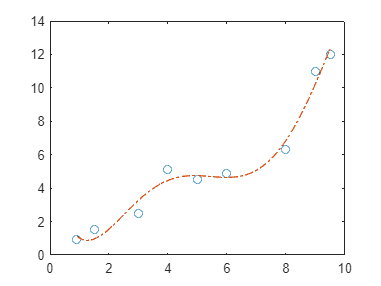

dataCurveFitX = [0.9 1.5 3 4 5 6 8 9 9.5];
dataCurveFitY = [0.9 1.5 2.5 5.1 4.5 4.9 6.3 11 12];

plot(dataCurveFitX, dataCurveFitY, 'o')
hold on

curveFit = polyfit(dataCurveFitX, dataCurveFitY, 5);

fitPolyX = [0.9:0.1:9.5];
fitPolyY = polyval(curveFit, fitPolyX);

plot(fitPolyX, fitPolyY, '-.')
hold off

## Directed Curve Fitting

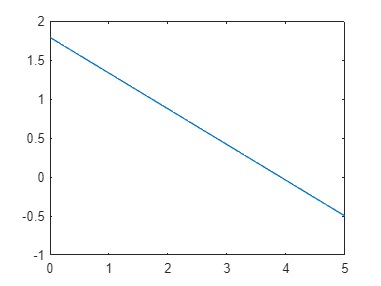

dirCurveFitX = [0:0.5:5];
dirCurveFitY = [6 4.83 3.7 3.15 2.41 1.83 1.49 1.21 0.96 0.73 0.64];

dirCurveFit = polyfit(dirCurveFitX, log(dirCurveFitY), 1);

dirFitX = [0:0.05:5];
dirFitY = polyval(dirCurveFit, dirFitX);

plot(dirFitX, dirFitY)

## Interpolation

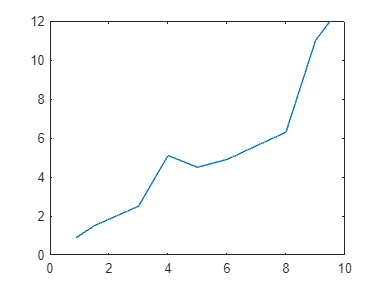

% Lerp
plot(dataCurveFitX, dataCurveFitY)

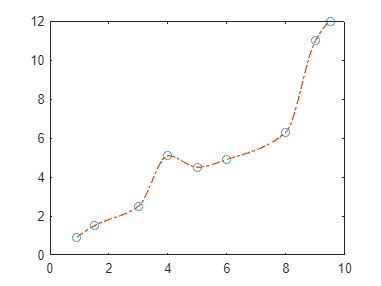


interpX = dataCurveFitX;
interpY = dataCurveFitY;
interpXViz = [0.9:0.1:9.5];
interpYViz = interp1(interpX, interpY, interpXViz,'pchip');

plot(dataCurveFitX, dataCurveFitY, 'o',...
     interpXViz, interpYViz, '-.')

## Min, Max, Zero

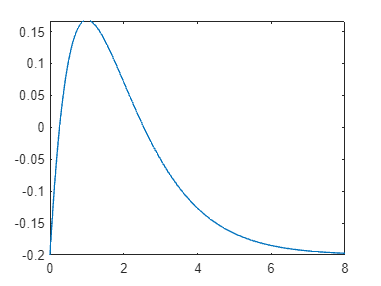

fplot('x*exp(-x)-0.2', [0 8])


[xMin, valMin] = fminbnd('-x*exp(-x)-0.2', 0, 8)

xMin = 1.0000

valMin = -0.5679


expZero = fzero('x*exp(-x)-0.2', 5)

expZero = 2.5426